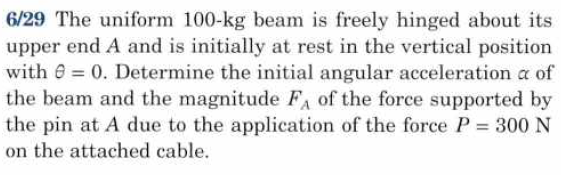

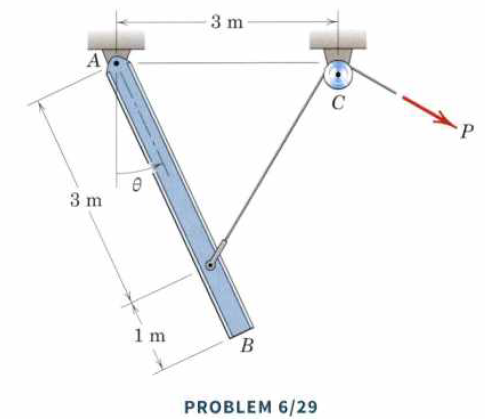

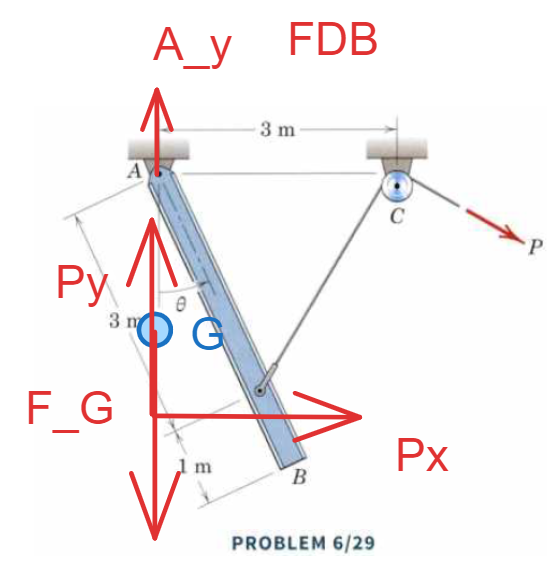

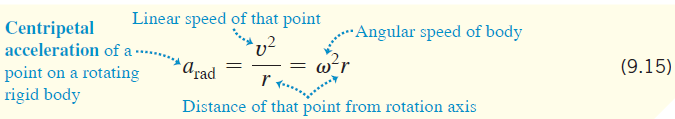

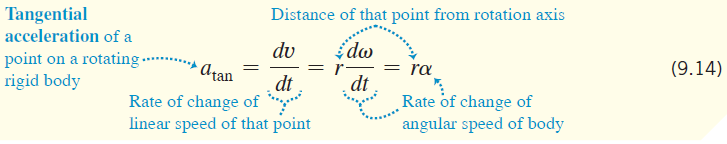

clear all
theta = atan(1)

theta =        0.7854


rad2deg(theta)

ans =     45


syms A_y
P = 300;
g = 9.81;
m = 100 %kg

m =    100


P_y = P * sin(theta)

P_y =        212.13


F_G = g * m

F_G =    981


F_rad = 0; %omega^2 * r
eq_Ay = A_y + P_y - F_G == F_rad

$$eq\_Ay = A_{y}+150\,\sqrt{2}-981=0$$


sol = solve(eq_Ay, A_y);
A_y = vpa(sol, 5)

$$A\_y = 768.87$$

veinkel accelerationen

P_x = P * cos(theta)
r = 3; %m
M = P_x * r

M =         636.4


l = 4;
I = 1/3 * m * l^2

I =        533.33



% M = I * alpha
alpha = M/I

alpha =        1.1932


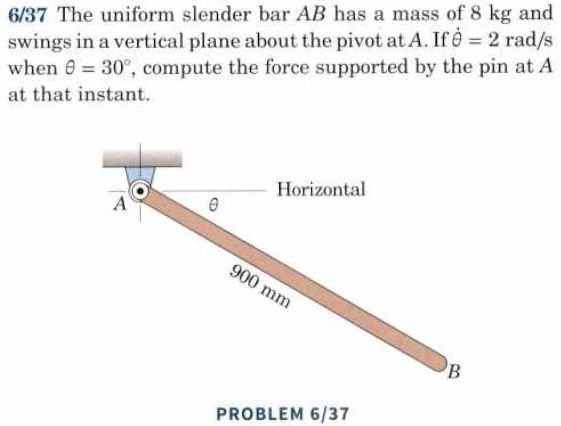

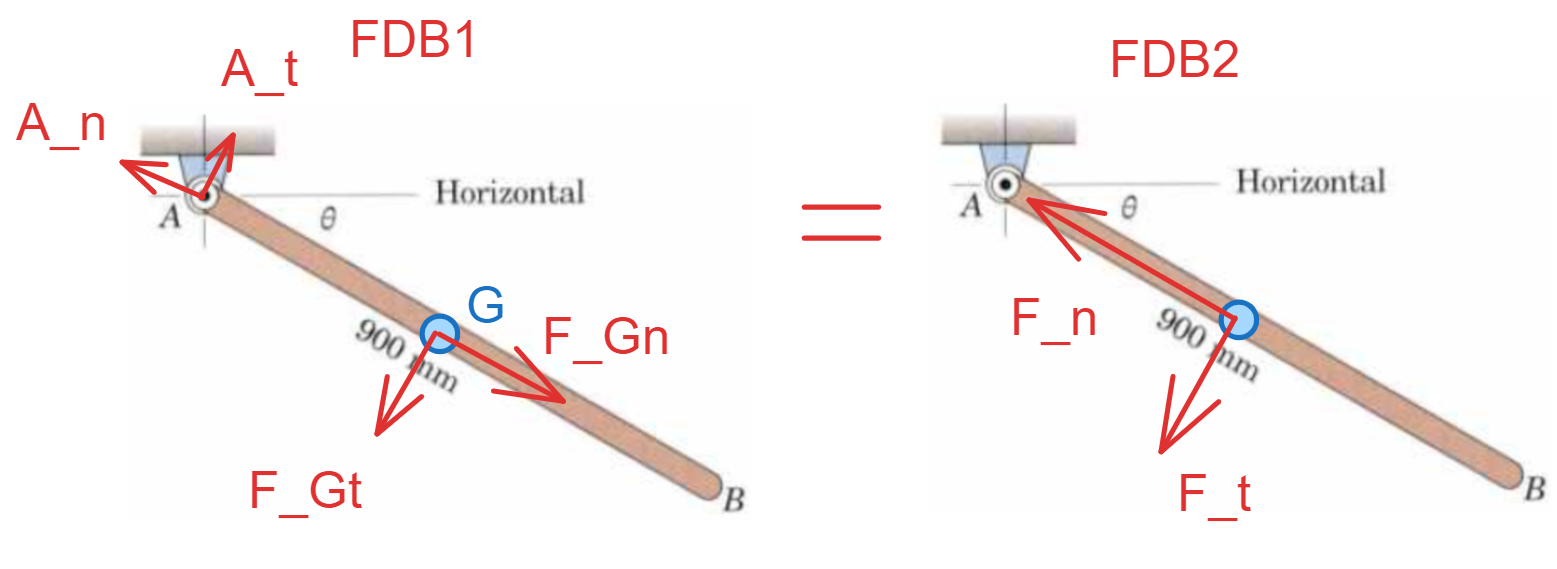

clear all
g = 9.81;
m = 8; % kg
syms A_y A_x
theta = 30;
l = 0.9

l =           0.9


r = l/2; %afstand til tyngdepunktet
omega = 2;
G_y = m * g * sind(theta)

G_y =         39.24


G_x = m * g * cosd(theta)

G_x =        67.966


F_n = omega^2 * r * m

F_n =          14.4


% M = I * alpha

I = 1/3 * m * l^2

I =          2.16


M = G_x * r

M =        30.585


alpha = M/I

alpha =         14.16



F_t = alpha * r * m

F_t =        50.974



eq_y = A_y - G_y == F_n

$$eq\_y = A_{y}-\frac{981}{25}=\frac{72}{5}$$

sol = solve(eq_y, A_y);
A_y = vpa(sol, 5)

$$A\_y = 53.64$$


eq_x = A_x - G_x == F_t

$$eq\_x = A_{x}-\frac{4782659104684023}{70368744177664}=-\frac{7173988657026035}{140737488355328}$$

sol = solve(eq_x, A_x);
A_x = vpa(sol, 5)

$$A\_x = 16.991$$

sqrt(A_y^2 + A_x^2) 

$$ans = 56.266845477598427508546501568699$$

    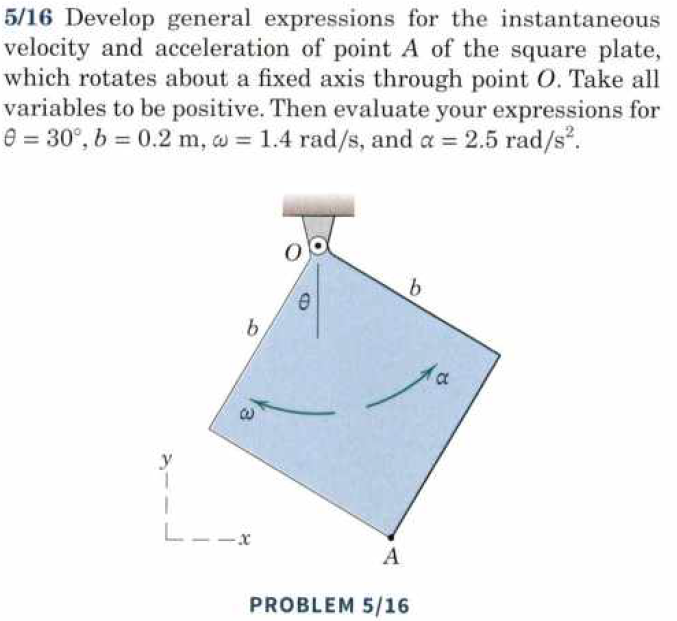

clear all
b = 0.2

b =           0.2


theta = 30;
y = -b * cosd(theta) - b * cosd(90 - theta)

y =      -0.27321


x = b * cosd(theta) - b * cosd(90 - theta)

x =      0.073205


r = [x; y; 0];
omega = [0; 0; -1.4];
alpha = [0; 0; 2.5];
v = cross(omega, r) 

v =      -0.38249
     -0.10249
            0


a_n = cross(omega,cross(omega,r))

a_n =      -0.14348
      0.53548
            0


a_t = cross(alpha, r)

a_t =       0.68301
      0.18301
            0


a = a_n + a_t

a =       0.53953
      0.71849
            0


% v_A = [-0.382; -0.1025; 0]
% a_A = [0.540; 0.718; 0]

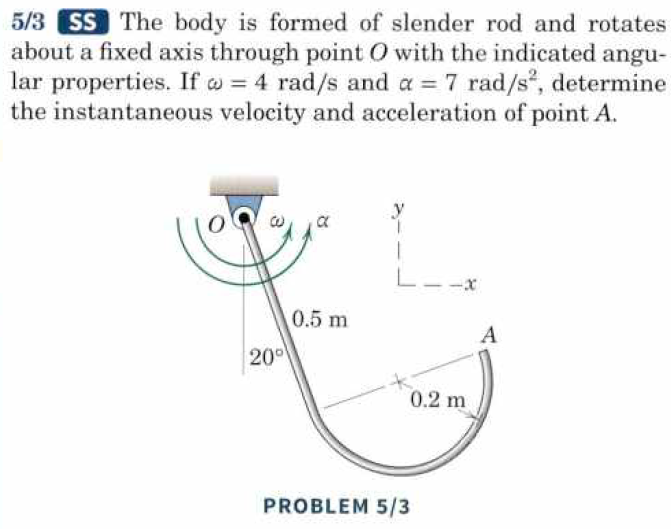

theta = 20;
0.5 * sind(theta)

ans =       0.17101


0.4 * cosd(theta)

ans =       0.37588


x = 0.5 * sind(theta) + 0.4 * cosd(theta)

x =       0.54689


y = -0.5 * cosd(theta) + 0.4 * sind(theta)

y =      -0.33304


r = [x; y; 0]

r =       0.54689
     -0.33304
            0


omega = [0; 0; 4];
alpha = [0; 0; 7];

v = cross(omega, r) 

v =        1.3322
       2.1875
            0


a_n = cross(omega, cross(omega,r) )

a_n =       -8.7502
       5.3286
            0


a_t = cross(alpha, r)

a_t =        2.3313
       3.8282
            0


a = a_n + a_t

a =       -6.4189
       9.1568
            0


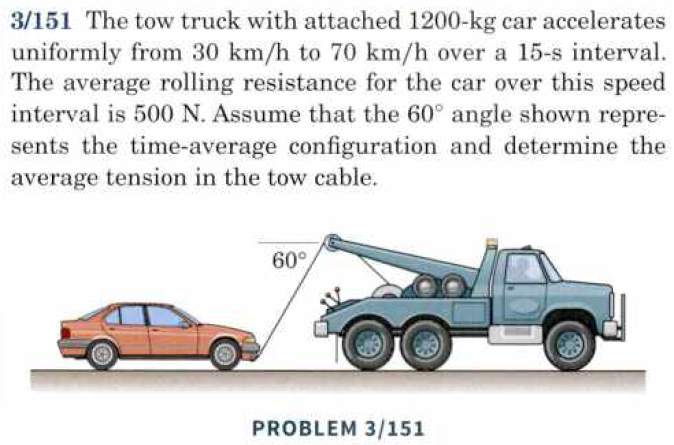

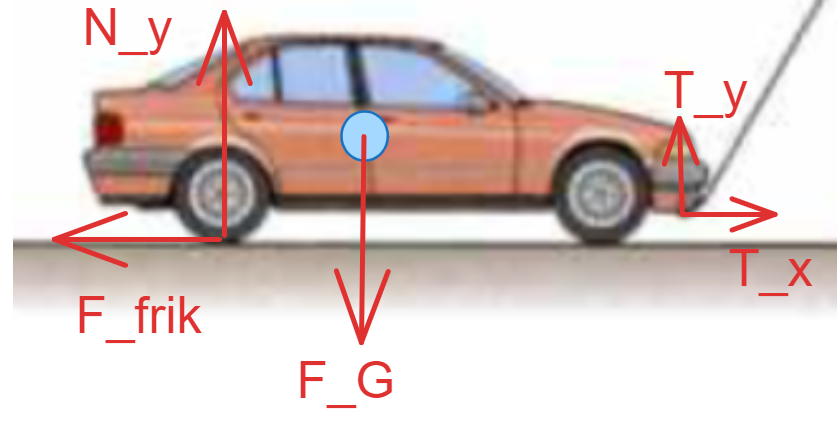

Her kan summes


$$\sum F_x = m\cdot a$$



$$\sum F_y = 0$$


clear all
m = 1200;
v_i = 30 / 3.6 % m/s

v_i =        8.3333


v_f = 70 / 3.6 % m/s

v_f =        19.444


g = 9.81;
t = 15; %
F_frik = 500; %N
theta = 60;
syms a T N_y

% v_f = v_i + a * t
a = (v_f - v_i) / t 

a =       0.74074


F_G = m * g

F_G =        11772


eq_y = T * sind(theta) - F_G + N_y == 0;
eq_x = T * cosd(theta) - F_frik == m*a;

sol = solve([eq_y, eq_x], [T, N_y]);
T = vpa(sol.T, 5)

$$T = 2777.8$$

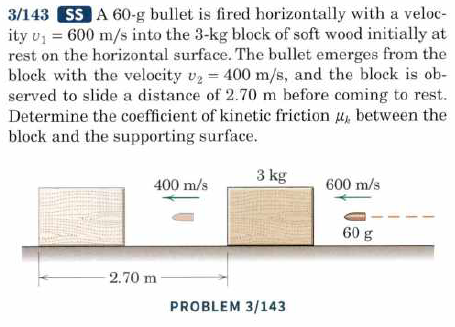

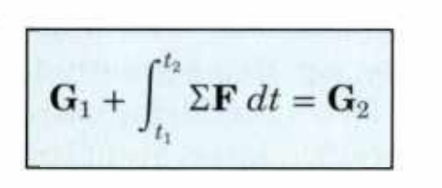

m_bullet = 0.060;
v_bullet_1 = 600;
m_block = 3;
v_block_1 = 0;
v_bullet_2 = 400;
syms v_block_2 mu_K
d = 2.70;
eq_impuls = v_bullet_1 * m_bullet + v_block_1 * m_block == v_bullet_2 * m_bullet + v_block_2 * m_block

$$eq\_impuls = 36=3\,v_{\mathrm{block},2}+24$$

v_block_2 = solve(eq_impuls, v_block_2)

$$v\_block\_2 = 4$$

T_block = 1/2 * m_block * v_block_2^2

$$T\_block = 24$$

g = 9.81;
F_frik = m_block * g * mu_K;
U_frik = F_frik * d;

eq_energi = T_block - U_frik == 0;
sol1 = solve(eq_energi, mu_K)

$$sol1 = \frac{8000}{26487}$$

mu_k = vpa(sol1, 5)

$$mu\_k = 0.30203$$

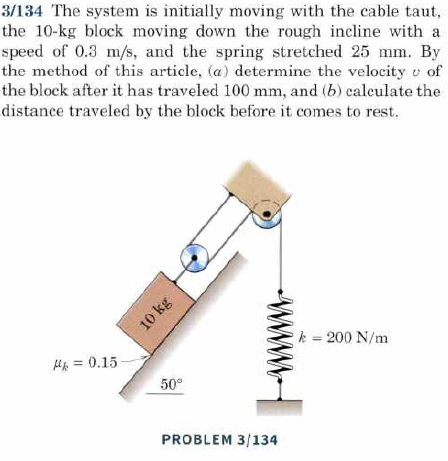

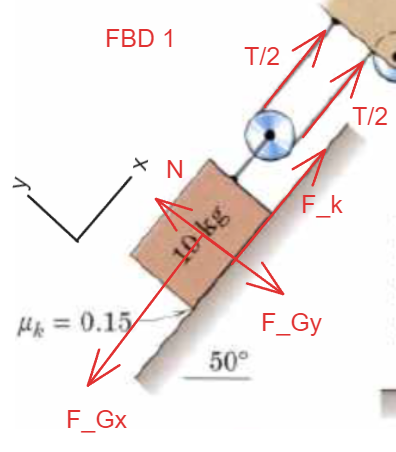            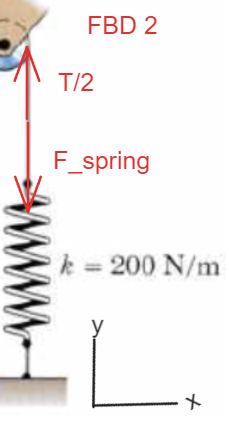

clear all
clf
m_block = 10;
v_block_1 = 0.3;
x_spring_1 = 0.025;
g = 9.81;

x_block = 0.100;

mu_k = 0.15;
theta = 50;
k = 200; %Nm

T_1 = 1/2 * m_block * v_block_1^2 

T_1 = 0.4500

U_frik = m_block * g * cosd(theta) * mu_k * x_block

U_frik = 0.9459

V_fjeder_1 = 1/2 * k * x_spring_1^2

V_fjeder_1 = 0.0625

h_1 = 0;%x_block * sind(theta)
V_G1 = m_block * g * h_1

V_G1 = 0

syms v_block_2
T_2 = 1/2 * m_block * v_block_2^2 

$$T\_2 = 5\,{v_{\mathrm{block},2}}^{2}$$

h_2 = -x_block * sind(theta)

h_2 = -0.0766

V_G2 = m_block * g * h_2 % m_block * g * sind(theta) * x_block%

V_G2 = -7.5149

x_spring_2 = 2 * x_block;
V_fjeder_2 = 1/2 * k * (x_spring_2 + x_spring_1)^2

V_fjeder_2 = 5.0625

eq = T_1 - U_frik + V_fjeder_1 + V_G1 == T_2 + V_fjeder_2 + V_G2;

sol = solve(eq, v_block_2);
v_block_2 = vpa(sol(2), 5)

$$v\_block\_2 = 0.63546$$

syms x_block

T_1 = 1/2 * m_block * v_block_1^2 

T_1 = 0.4500

U_frik = m_block * g * cosd(theta) * mu_k * x_block % <---

$$U\_frik = \frac{5324729506336649\,x_{\mathrm{block}}}{562949953421312}$$

V_fjeder_1 = 1/2 * k * x_spring_1^2

V_fjeder_1 = 0.0625

h_1 = 0;%x_block * sind(theta)
V_G1 = m_block * g * h_1  

V_G1 = 0


T_2 = 0;
h_2 = -x_block * sind(theta)  % <---

$$h\_2 = -\frac{6899914937159737\,x_{\mathrm{block}}}{9007199254740992}$$

V_G2 = m_block * g * h_2 % m_block * g * sind(theta) * x_block%

$$V\_G2 = -\frac{6768816553353701997\,x_{\mathrm{block}}}{90071992547409920}$$

x_spring_2 = 2 * x_block;  % <--- fjederen strækkes dobbelt så langt som blokken rejser
V_fjeder_2 = 1/2 * k * (x_spring_2 + x_spring_1)^2

$$V\_fjeder\_2 = 100\,{\left(2\,x_{\mathrm{block}}+\frac{1}{40}\right)}^{2}$$

eq2 = T_1 - U_frik + V_fjeder_1 + V_G1 == T_2 + V_fjeder_2 + V_G2

$$eq2 = \frac{41}{80}-\frac{5324729506336649\,x_{\mathrm{block}}}{562949953421312}=100\,{\left(2\,x_{\mathrm{block}}+\frac{1}{40}\right)}^{2}-\frac{6768816553353701997\,x_{\mathrm{block}}}{90071992547409920}$$


sol = solve(eq2, x_block);
x_block = vpa(sol(2), 5)

$$x\_block = 0.14688$$

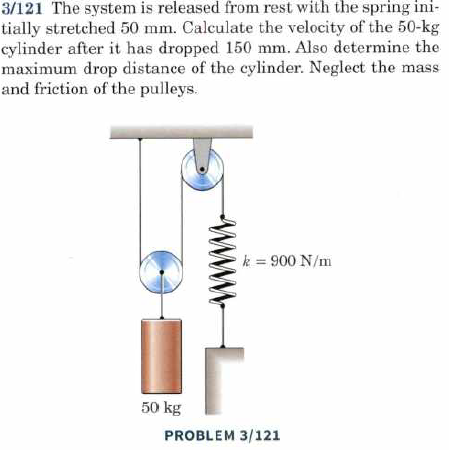

clear all
x_spring_1 = 0.050;
m_cyl = 50;
x_cyl = 0.150;
k = 900;
g = 9.81;

T_1 = 0;
V_pot_1 = 0;
V_fjeder_1 = 1/2 * k * x_spring_1^2

V_fjeder_1 = 1.1250


syms v_cyl_2
T_2 = 1/2 * m_cyl * v_cyl_2^2

$$T\_2 = 25\,{v_{\mathrm{cyl},2}}^{2}$$

h_2 = -x_cyl;
V_pot_2 = m_cyl * g * h_2

V_pot_2 = -73.5750

V_fjeder_2 = 1/2 * k * (2*x_cyl + x_spring_1)^2

V_fjeder_2 = 55.1250


eq = T_1 + V_pot_1 + V_fjeder_1 == T_2 + V_pot_2 + V_fjeder_2

$$eq = \frac{9}{8}=25\,{v_{\mathrm{cyl},2}}^{2}-\frac{369}{20}$$

sol = solve(eq, v_cyl_2);
v_cyl_2 = vpa(sol(2), 5)

$$v\_cyl\_2 = 0.88487$$

syms x_cyl
T_1 = 0;
V_pot_1 = 0;
V_fjeder_1 = 1/2 * k * x_spring_1^2

V_fjeder_1 = 1.1250



T_2 = 0;
h_2 = -x_cyl;
V_pot_2 = m_cyl * g * h_2

$$V\_pot\_2 = -\frac{981\,x_{\mathrm{cyl}}}{2}$$

V_fjeder_2 = 1/2 * k * (2*x_cyl + x_spring_1)^2

$$V\_fjeder\_2 = 450\,{\left(2\,x_{\mathrm{cyl}}+\frac{1}{20}\right)}^{2}$$


eq2 = T_1 + V_pot_1 + V_fjeder_1 == T_2 + V_pot_2 + V_fjeder_2

$$eq2 = \frac{9}{8}=450\,{\left(2\,x_{\mathrm{cyl}}+\frac{1}{20}\right)}^{2}-\frac{981\,x_{\mathrm{cyl}}}{2}$$

sol = solve(eq2, x_cyl)

$$sol = \left(\begin{array}{c} 0\\ \frac{89}{400} \end{array}\right)$$

x_cyl = vpa(sol(2), 6)

$$x\_cyl = 0.2225$$

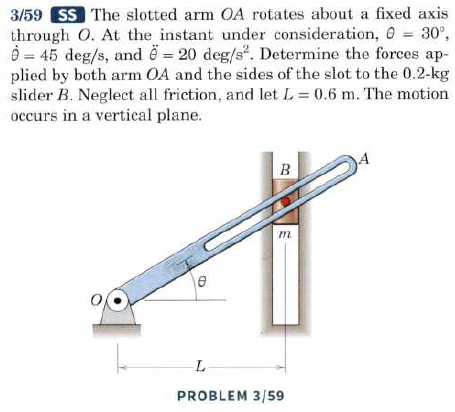

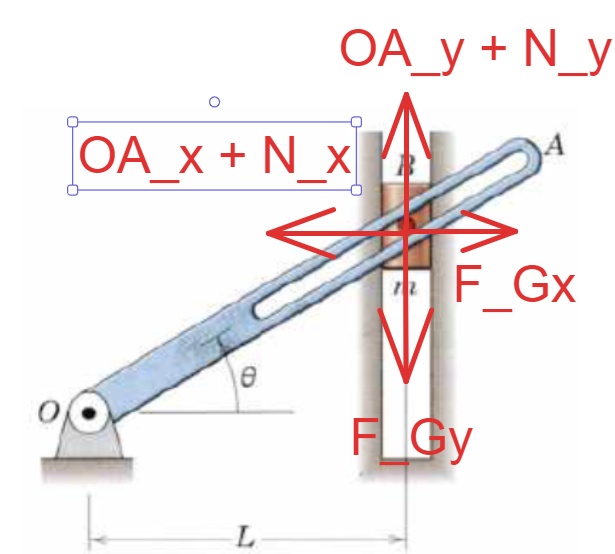

theta = 30;
omega = 45;
alpha = 20;
m = 0.2;
L = 0.6;
g = 9.81;
syms N a

r =  L / sind(90 - theta)  %L/tand(theta)

r = 0.6928


F_t = m * r * alpha

F_t = 2.7713

OA_x = F_t * cosd(theta)

OA_x = 2.4000

OA_y = F_t * sind(theta)

OA_y = 1.3856

OA = norm([OA_x; OA_y])

OA = 2.7713

F_Gx = m * g * sind(theta)

F_Gx = 0.9810

F_Gy = m * g * cosd(theta)

F_Gy = 1.6991

F_G = norm([F_Gx; F_Gy])

F_G = 1.9620

N_x = N * sind(theta)

$$N\_x = \frac{N}{2}$$

N_y = N * cosd(theta)

$$N\_y = \frac{\sqrt{3}\,N}{2}$$

% N = norm([N_x; N_y])

eq_x = OA_x - F_Gx + N_x == 0

$$eq\_x = \frac{N}{2}+\frac{1419}{1000}=0$$

eq_y = OA_y - F_Gy + N_y == m*a

$$eq\_y = \frac{\sqrt{3}\,N}{2}-\frac{1411883870251267}{4503599627370496}=\frac{a}{5}$$


sol = solve([eq_x, eq_y], [N, a]);
N = vpa(sol.N, 5)

$$N = -2.838$$

OA + F_G + N

$$ans = 1.8952812921102122345473617315292$$

a = vpa(sol.a, 5)

$$a = -13.856$$

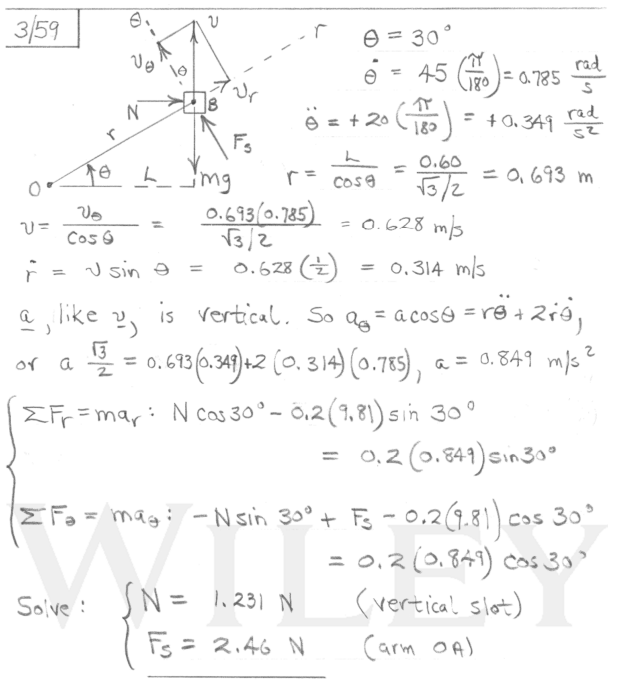

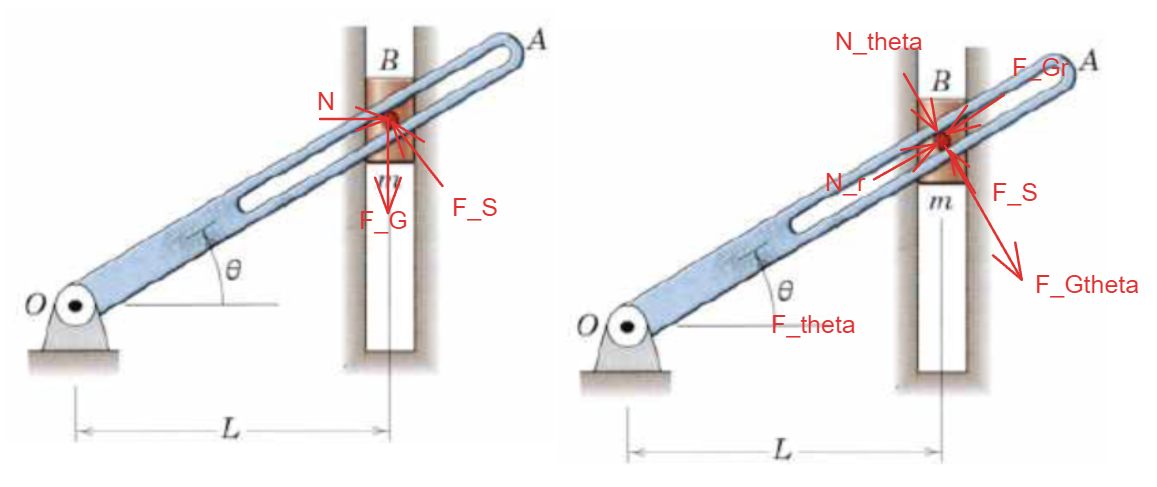

clear all
theta = deg2rad(30);
omega = deg2rad(45);
alpha = deg2rad(20);
m = 0.2;
L = 0.6;
g = 9.81;
syms N F_s

r =  L / cos(theta)  %L/tand(theta)

r = 0.6928

N_r = N * cos(theta)

$$N\_r = \frac{\sqrt{3}\,N}{2}$$

N_theta = N * sin(theta)

$$N\_theta = \frac{N}{2}$$


F_Gr = m * g * sin(theta)

F_Gr = 0.9810

F_Gtheta = m * g * cos(theta)

F_Gtheta = 1.6991

v_theta = r * omega

v_theta = 0.5441

v = v_theta / cos(theta)

v = 0.6283

r_dot = v * sin(theta)

r_dot = 0.3142

a_theta = r * alpha + 2 * r_dot * omega

a_theta = 0.7353

a = a_theta / cos(theta)

a = 0.8491

r_ddot = a * sin(theta)

r_ddot = 0.4245

a_r = r_ddot % da vi har et øjebliks billede

a_r = 0.4245

%- r * omega^2  %a * sin(theta) %r_ddot - r_dot * omega^2 

eq_F_r = N_r - F_Gr == m * a_r; 
eq_F_theta = F_s - N_theta - F_Gtheta  == m * a_theta; % * cosd(theta)

sol = solve([eq_F_r, eq_F_theta], [N, F_s]);
N = vpa(sol.N, 5)

$$N = 1.2308$$

F_s = vpa(sol.F_s, 5)

$$F\_s = 2.4616$$